# State feedback control, state estimation, discrete systems: Case studies

The script assumes familiarity with all of the earlier files in the state space section of the toolbox. The purpose here is to undertake case studies showing how the different analysis and design tool can be used to formulate a complete control feedback design, here with a focus on single-input-single-output discrete systems The design method used here is pole placement. This live script needs the control toolbox. 

These notes give a concise engineering and analytical background alongside some simple MATLAB code snippets that can be used for equivalent analysis. In addition to the files referred above this file summarises the principles and visualises them with block diagrams. 

To avoid excessive displays of matrices, in many cases the results are not automatically displayed. Remove the semi-colons and use run section to view details you may be interested in.

### Resources, similar files and the toolbox

**Control Engineering **and** Control Engineering: MATLAB Exercises, by L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász, Springer, 2019**

Also see website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

[Modelling, Dynamics and Control - Chapter seven: State space methods](https://sites.google.com/sheffield.ac.uk/controleducation/statespacemethods)

***discrete_models_and_usage, discrete_time_state_space_models_control101, State_feedback_and_state_estimation_cont_case_study***

**For more information on the toolbox uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  
%
% There is a bug in 2024a: Try doc ("Control101 Toolbox")  or doc control101_toolbox. 
%
% help control101  % this line only works if the toolbox is installed

File written by Ruth Bars and László Keviczky, Budapest University of Technology and Economics with edits by J.A. Rossiter, University of Sheffield  

                                                                                       

## Table of contents

- State space representation of discrete single input single output systems

- The concept of state feedback control

- State feedback with pole placement

- Introducing an integrator into the control loop

- State estimation

- State feedback with state estimation

## 1. State space representation of discrete single input single output system

The set $\lbrace \mathit{\mathbf{A}},\mathit{\mathbf{b}},{\mathit{\mathbf{c}}}^T ,d\rbrace$ of parameter matrices exhibits a continuous SISO system representation with input *u, *output *y *and state vector ***x ***in the model


$$\begin{array}{l}
\dot{x} =\textrm{Ax}+\textrm{bu}\\
y={\mathit{\mathbf{c}}}^T \mathit{\mathbf{x}}+\textrm{du}
\end{array}$$


***A*** is an *n* X *n* quadratic matrix, ***b*** is an *n* X 1 column vector, ${\mathit{\mathbf{c}}}^T$is a 1 X *n* row vector and *d* is a constant. The system model characterised by the four parameters  is called state model.

The solution of the state equation for ***x***(0) initial conditions and *u*(t) the input signal is:


$$\mathit{\mathbf{x}}\left(t\right)=e^{\mathit{\mathbf{A}}\left(t-t_0 \right)} \mathit{\mathbf{x}}\left(0\right)+\int_{t_0 }^t e^{\mathit{\mathbf{A}}\left(t-\tau \right)} \mathit{\mathbf{b}}\;\;u\left(\tau \right)\;d\tau$$


A zero order holding element is applied, so between two consecutive sampling points the input signal does not change. Executing the integration between $t_0 =\textrm{kT}$ and $t=\left(k+1\right)T$, where T is the sampling time and assuming that matrix ***A*** is invertible, then:


$$\mathit{\mathbf{x}}\left\lbrack \left(k+1\right)\;T\right\rbrack =e^{\mathit{\mathbf{A}}\;T} \mathit{\mathbf{x}}\left(\textrm{kT}\right)+{\mathit{\mathbf{A}}}^{-1} \left(e^{\mathit{\mathbf{A}}\;T} -\mathit{\mathbf{I}}\right)\mathit{\mathbf{b}}\;u\left(\textrm{kT}\right)$$


By simplifying the notation as $u\left(\textrm{kT}\right)=u\left\lbrack k\right\rbrack$  and  $\mathit{\mathbf{x}}\left\lbrack \left(k+1\right)\;T\right\rbrack =\mathit{\mathbf{x}}\left\lbrack k+1\right\rbrack$ the discrete state equation can be written as


$$\mathit{\mathbf{x}}\left\lbrack k+1\right\rbrack =\textrm{Fx}\left\lbrack k\right\rbrack +\mathit{\mathbf{g}}u\left(\textrm{kT}\right)$$



$$y\left\lbrack k\right\rbrack ={\mathit{\mathbf{c}}}^T \mathit{\mathbf{x}}\left\lbrack k\right\rbrack +\textrm{du}\left\lbrack k\right\rbrack$$


where $\mathit{\mathbf{F}}=e^{\mathit{\mathbf{A}}\;T}$ and  $\mathit{\mathbf{g}}={\mathit{\mathbf{A}}}^{-1} \left(e^{\mathit{\mathbf{A}}\;T} -\mathit{\mathbf{I}}\right)\mathit{\mathbf{b}}$. In most practical cases *d*=0.

A block diagram representation of the discrete state equation supposing d=0 is shown in the figure 1 below.

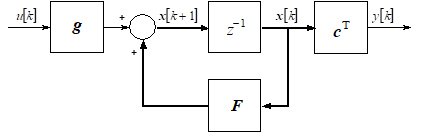

**Figure 1**: Block diagram representation of a discrete state space model

### 1.1 Example 1.

The transfer function of a continuous system is $P\left(s\right)=\frac{1}{\left(1+5s\right)\left(1+10s\right)}$. The process is sampled with sampling time T=2.5.  Determine the state equations of the continuous and the discrete (sampled) system.

disp('SECTION 1.1: DETERMINE THE STATE EQUATIONS')

SECTION 1.1: DETERMINE THE STATE EQUATIONS


disp('THE TRANSFER FUNCTION OF THE CONTINUOUS SYSTEM')

THE TRANSFER FUNCTION OF THE CONTINUOUS SYSTEM


s=zpk('s');
P=1/((1+5*s)*(1+10*s))

P =
 
       0.02
  ---------------
  (s+0.2) (s+0.1)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('THE CONTINUOUS STATE SPACE MODEL')

THE CONTINUOUS STATE EQUATION


Sysc=ss(P);
[A,b,c,d]=ssdata(Sysc)

A =    -0.1000    1.0000
         0   -0.2000


b =          0
    0.1250


c =     0.1600         0


d = 0

disp('The sampling time')

The sampling time


T=2.5

T = 2.5000

disp('THE DISCRETE STATE SPACE MODEL')

THE DISCRETE STATE EQUATION


Sysd=c2d(Sysc,T,'zoh');
[F,g,c,d]=ssdata(Sysd)

F =     0.7788    1.7227
         0    0.6065


g =     0.3058
    0.2459


c =     0.1600         0


d = 0

You can confirm that the state space model is as expected by computing the transition matrix directly, for example:

disp('Check the state matrices using the transformation formula')

Check the state matrices according to the transformation formula given above


F1=expm(A*T)

F1 =     0.7788    1.7227
         0    0.6065


g1=inv(A)*(expm(A*T)-eye(2))*b

g1 =     0.3058
    0.2459


### 1.2 Example 2  

The transfer function of a continuous system is $P\left(s\right)=\frac{1}{\left(1+5s\right)\left(1+10s\right)}$. The process is sampled with sampling time T=2.5. Determine the discrete state equation from the pulse transfer function. Give the step responses of the system and the response of the state variables to given initial conditions.

disp('SECTION 1.2: DETERMINE THE DISCRETE STATE SPACE MODEL FROM THE PULSE TRANSFER FUNCTION')

SECTION 1.2: DETERMINE THE DISCRETE STATE SPACE MODEL FROM THE PULSE TRANSFER FUNCTION


disp('THE TRANSFER FUNCTION OF THE CONTINUOUS SYSTEM')

THE TRANSFER FUNCTION OF THE CONTINUOUS SYSTEM


s=zpk('s');
P=1/((1+5*s)*(1+10*s))

P =
 
       0.02
  ---------------
  (s+0.2) (s+0.1)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The sampling time')

The sampling time


T=2.5

T = 2.5000

z=zpk('z',T);
disp('THE PULSE TRANSFER FUNCTION')

THE PULSE TRANSFER FUNCTION


Pz=c2d(P,T)

Pz =
 
   0.048929 (z+0.7788)
  ---------------------
  (z-0.7788) (z-0.6065)
 
Sample time: 2.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('THE DISCRETE STATE EQUATION')

THE DISCRETE STATE EQUATION


Sysz=ss(Pz)

Sysz =
 
  A = 
           x1      x2
   x1  0.6065   1.177
   x2       0  0.7788
 
  B = 
         u1
   x1     0
   x2  0.25
 
  C = 
           x1      x2
   y1  0.2304  0.1957
 
  D = 
       u1
   y1   0
 
Sample time: 2.5 seconds
Discrete-time state-space model.


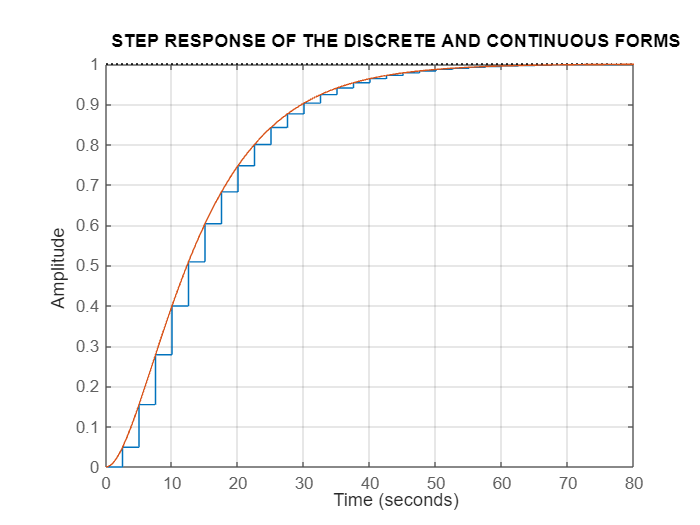

% [F,g,c,d]=ssdata(Sysz) extract matrix data if needed

% system responses
tfinal=80;
step(Sysz,P,tfinal),grid
title('STEP RESPONSES OF THE DISCRETE AND CONTINUOUS FORMS')


disp('INITIAL CONDITIONS')

INITIAL CONDITIONS


x0=[1;1]

x0 =      1
     1


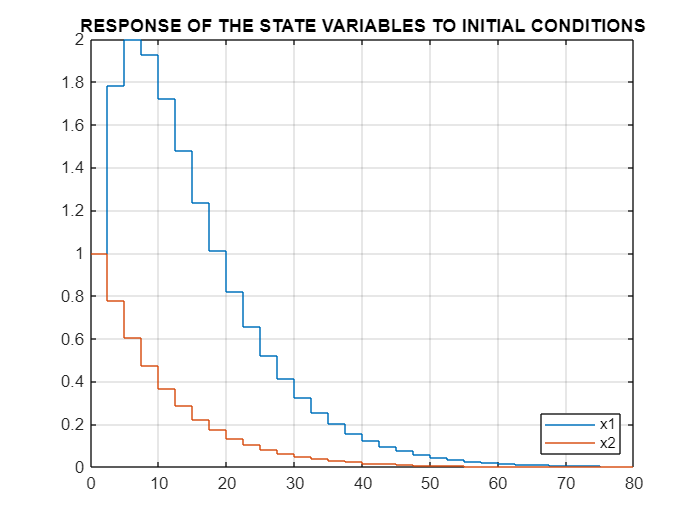

[y,t,x]=initial(Sysz,x0,tfinal);
stairs(t,x),grid
legend('x1','x2','Location','southeast')
title('RESPONSE OF THE STATE VARIABLES TO INITIAL CONDITIONS')

## 2. The concept of state feedback control

 The poles of the system in the *z* domain are the roots of the characteristic equation:


$$\det \left(z\;\mathit{\mathbf{I}}-\mathit{\mathbf{F}}\right)=0$$


One aim of  control is often the acceleration of the system (or stabilisation of an unstable process). One control method is state feedback. Prescribing the required poles of the closed loop system defines the rate of acceleration.

By state feedback the control signal is obtained from the state variables feeding them back to the input through the constant elements of vector ${\mathit{\mathbf{k}}}^T$. The reference signal also influences the value of the control signal. The block diagram of state feedback control is shown in the figure 2 below. State feedback modifies both the static and the dynamic response of the system between the reference signal and the output signal.  

                    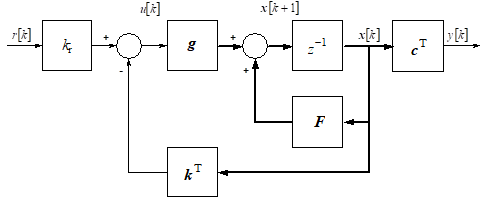

**Figure 2**: Block diagram representation of a discrete state space model  with state feedback

The control signal is obtained as:


$$u\left\lbrack k\right\rbrack =k_r r\left\lbrack k\right\rbrack -{\mathit{\mathbf{k}}}^T \mathit{\mathbf{x}}\left\lbrack k\right\rbrack$$


$k_r$ is a compensation factor ensuring the required steady state value. The state equations of the closed loop supposing d=0 can be written as:


$$\mathit{\mathbf{x}}\left\lbrack k+1\right\rbrack =\left(\mathit{\mathbf{F}}-\mathit{\mathbf{g}}{\;k}^T \right)\mathit{\mathbf{x}}\left\lbrack k\right\rbrack +{\mathrm{k}}_r \;\mathit{\mathbf{g}}\;r\left\lbrack k\right\rbrack$$



$$y\left\lbrack k\right\rbrack ={\mathit{\mathbf{c}}}^T \mathit{\mathbf{x}}\left\lbrack k\right\rbrack$$


The characteristic equation of the state feedback system is:


$$\det \left(z\;\mathit{\mathbf{I}}-F+\mathit{\mathbf{g}}\;{\mathit{\mathbf{k}}}^T \right)=0$$


Its poles can be prescribed by suitable choice of ***k*** to ensure the required behaviour.

## 3. State feedback with pole placement

The design of state feedback is executed in three steps.

a. Choose the desired location of the poles of the closed loop system.

b. Determine the state feedback vector ensuring the given poles using the Ackermann formula (eg. ***state_feedback_control101***). The matlab command `acker` can be applied, which can be used both for continuous and discrete systems. (For theoretical background and exercises look at  [state space feedback 4 - ackermanns approachpdf.pdf ](https://drive.google.com/file/d/1Vo2Q2bjeqK3yDimv3zWOflkjr5edvBYk/view))


$$\mathit{\mathbf{k}}=\textrm{acker}\left(\mathit{\mathbf{F}},\mathit{\mathbf{g}},\mathit{\mathbf{R}}\right)$$


where ***R  ***is the vector of the discrete prescribed poles.

c. Determine the compensation factor to fulfill the static requirements.

#### 3.1 State feedback controller design for a third order proportional process

For the discrete case the same examples are considered as in the continuous case (***State_feedback_and_estimation_cont_case_study***). The transfer function of the continuous process is:


$$G\left(s\right)=\frac{6\ldotp 2}{\left(s+1\right)\left(s+2\right)\left(s+3\right)}$$


The sampling time is T=0.2. Zero order hold is applied. Determine the discrete state equation and choose the poles of the continuous closed loop as: *pk=[-6;-3+i*4;-3-i*4]*

Transform the poles to discrete ones by transformation $z=e^{\textrm{sT}}$. Determine the state feedback vector which shifts the poles of the dsicrete system to the given closed loop poles.

The associated design steps and a plot of the closed-loop the step response are given in the code below. Note that the use of $k_r$ (see ***tracking_with_statespace_control101 ) ***ensures a closed-loop gain of unity, in the nominal case whereas this may not be the case for the open-loop system.

disp('SECTION 3.1: DESIGN A STATE FEEDBACK CONTROLLER FOR A DISCRETE THIRD ORDER PROCESS')

SECTION 3.1: DESIGN A STATE FEEDBACK CONTROLLER FOR A DISCRETE THIRD ORDER PROCESS


disp('The process')

The process


clear
clf
num=6.2;
den=poly([-1,-2,-3]);
G=tf(num,den)

G =
 
           6.2
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.
Model Properties


[A,b,c,d]=tf2ss(num,den); % The controllability canonical form of the state equation
H=ss(A,b,c,d);
disp('The sampling time')

The sampling time


T=0.2

T = 0.2000

disp('The discrete state equation')

The discrete state equation


Hd=c2d(H,T,'zoh')

Hd =
 
  A = 
             x1        x2        x3
   x1    0.1977    -1.269   -0.6483
   x2    0.1081    0.8461  -0.08071
   x3   0.01345    0.1888     0.994
 
  B = 
              u1
   x1     0.1081
   x2    0.01345
   x3  0.0009927
 
  C = 
        x1   x2   x3
   y1    0    0  6.2
 
  D = 
       u1
   y1   0
 
Sample time: 0.2 seconds
Discrete-time state-space model.


[F,g,cd,dd]=ssdata(Hd);

% Feedback and feedforward design
disp('The prescribed poles of the continuous closed loop system')

The prescribed poles of the continuous closed loop system


Rc=[-6;-3+i*4;-3-i*4]

Rc =   -6.0000 + 0.0000i
  -3.0000 + 4.0000i
  -3.0000 - 4.0000i


disp('The prescribed poles of the discrete system')

The prescribed poles of the discrete system


Rd=exp(Rc*T)

Rd =    0.3012 + 0.0000i
   0.3824 + 0.3937i
   0.3824 - 0.3937i


disp('Determine the discrete state feedback vector')

Determine the discrete state feedback vector


k=acker(F,g,Rd)

k =     4.2463   32.4319   77.4220


disp('The parameter matrices of the closed loop')

The parameter matrices of the closed loop


Fc=F-g*k; gc=g; cc=cd;dc=dd;
Tk=ss(Fc,gc,cc,dc,T)

Tk =
 
  A = 
             x1        x2        x3
   x1   -0.2611    -4.774    -9.014
   x2   0.05094    0.4098    -1.122
   x3  0.009236    0.1566    0.9172
 
  B = 
              u1
   x1     0.1081
   x2    0.01345
   x3  0.0009927
 
  C = 
        x1   x2   x3
   y1    0    0  6.2
 
  D = 
       u1
   y1   0
 
Sample time: 0.2 seconds
Discrete-time state-space model.


disp('The static gain')

The static gain


kr=1/dcgain(Tk)

kr = 13.4552

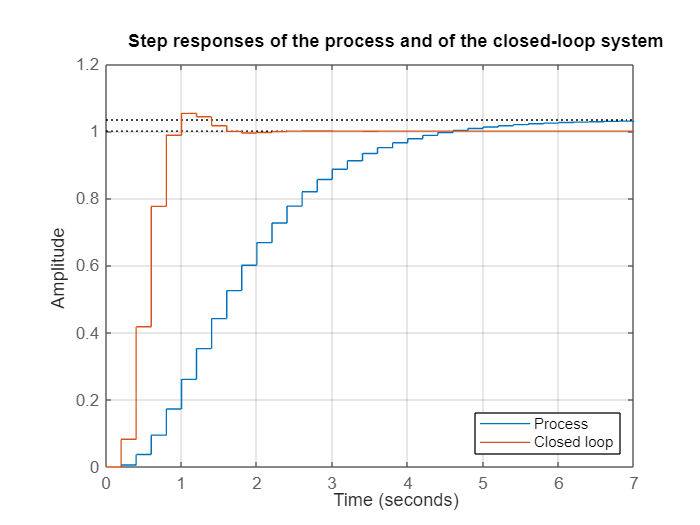


% Closed-loop responses
Fck=Fc;gck=kr*gc;cck=cc;dck=dc;
Tk1=ss(Fck,gck,cck,dck,T);  % The compensated state matrices
step(Hd,Tk1),grid
legend('Process','Closed loop','Location','Southeast')
title('Step responses of the process and of the closed-loop system')

#### 3.2 State feedback controller design for an unstable process

With state feedback unstable processes can be stabilised easily, just stable poles should be prescribed for the closed loop system. As an example consider the process given by the following transfer function:


$$G\left(s\right)=\frac{-6}{\left(s-1\right)\left(s+2\right)\left(s+3\right)}$$


The process is unstable as its transfer function contains one pole on the right side of the complex plane.

The sampling time is T=0.2. Zero order hold is applied. Determine the discrete state equation. Choose the poles of the closed loop of the continuous process as: *pk=[-6;-3+i*4;-3-i*4]*

- Transform the poles to discrete ones by transformation $z=e^{\textrm{sT}}$.

- Determine the state feedback vector in the discrete system which shifts the poles of the system to the given closed loop poles.

- Determine the state feedback vector and plot the step response of the closed loop.

The code below demonstrates how easily this can be done in MATLAB code.

disp('SECTION 3.2: DESIGN A STATE FEEDBACK CONTROLLER FOR AN UNSTABLE DISCRETE PROCESS')

SECTION 3.2: DESIGN A STATE FEEDBACK CONTROLLER FOR AN UNSTABLE DISCRETE PROCESS


disp('The process')

The process


clear
num=-6;
den=poly([1,-2,-3]);
G=tf(num,den)

G =
 
          -6
  -------------------
  s^3 + 4 s^2 + s - 6
 
Continuous-time transfer function.
Model Properties


[A,b,c,d]=tf2ss(num,den); %The controllability canonical form of the state equation
H=ss(A,b,c,d);

The sampling time


T=0.2;                    % The sampling time

T = 0.2000

disp('The discrete state equation')

The discrete state equation


Hd=c2d(H,T,'zoh')

Hd =
 
  A = 
             x1        x2        x3
   x1    0.4428  -0.04378    0.8223
   x2    0.1371    0.9911   0.09328
   x3   0.01555    0.1992     1.007
 
  B = 
             u1
   x1    0.1371
   x2   0.01555
   x3  0.001103
 
  C = 
       x1  x2  x3
   y1   0   0  -6
 
  D = 
       u1
   y1   0
 
Sample time: 0.2 seconds
Discrete-time state-space model.


[F,g,cd,dd]=ssdata(Hd);

% Control design
disp('The prescribed poles of the continuous closed loop system')

The prescribed poles of the continuous closed loop system


Rc=[-6;-3+i*4;-3-i*4]

Rc =   -6.0000 + 0.0000i
  -3.0000 + 4.0000i
  -3.0000 - 4.0000i


disp('The prescribed poles of the discrete system')

The prescribed poles of the discrete system


Rd=exp(Rc*T)

Rd =    0.3012 + 0.0000i
   0.3824 + 0.3937i
   0.3824 - 0.3937i


disp('Determine the discrete state feedback vector using the Ackermann formula')

Determine the discrete state feedback vector using the Ackermann formula


k=acker(F,g,Rd)

k =     5.3565   35.9286   74.3002


disp('The parameter matrices of the closed loop')

The parameter matrices of the closed loop


Fc=F-g*k; gc=g; cc=cd;dc=dd;
Tk=ss(Fc,gc,cc,dc,T)

Tk =
 
  A = 
            x1       x2       x3
   x1  -0.2913   -4.968   -9.361
   x2  0.05378   0.4325   -1.062
   x3  0.00964   0.1596   0.9247
 
  B = 
             u1
   x1    0.1371
   x2   0.01555
   x3  0.001103
 
  C = 
       x1  x2  x3
   y1   0   0  -6
 
  D = 
       u1
   y1   0
 
Sample time: 0.2 seconds
Discrete-time state-space model.


disp('The static gain')

The static gain


kr=1/dcgain(Tk)

kr = -11.3834

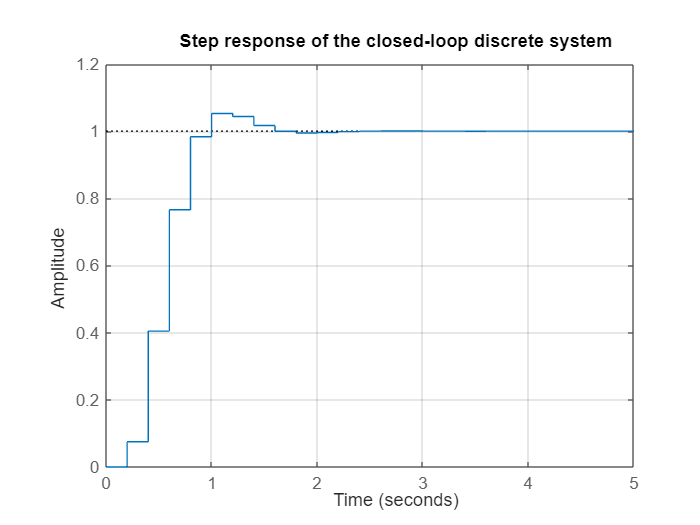


% CLosed-loop simulation
Fck=Fc;gck=kr*gc;cck=cc;dck=dc;
Tk1=ss(Fck,gck,cck,dck,T); % The compensated state matrices
step(Tk1,5),grid
title('Step response of the closed-loop discrete system')

## 4. Introducing an integrator into the control loop

As discussed in the file ***tracking_with_statespace_control101***, the feedback factor will only ensure accurate tracking in the nominal case and more typical, the model is only an approximation of the real process.  Moreover, disturbance rejection is not ensured either. In general integral action is needed to achieve offset free tracking.  A simple approach is to enhance the state equation with an extra state variable which is the integral of the output signal the accurate step reference tracking and step disturbance rejection can then also be realised.

### 4.1. Background on inlcuding integral action

The block diagram of the discrete integrator is shown in the figure 4.1 below.

                                    

**Figure 4.1:** Discrete integration

The difference equation of the discrete integrator is:


$$x_i \left\lbrack k+1\right\rbrack =x_i \left\lbrack k\right\rbrack +\textrm{Ty}\left\lbrack k\right\rbrack =x_i \left\lbrack k\right\rbrack +T{\mathit{\mathbf{c}}}^T \mathit{\mathbf{x}}\left\lbrack k\right\rbrack$$


The extended state equation is:


$$\left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\left\lbrack k+1\right\rbrack \\
x_i \left\lbrack k+1\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\mathit{\mathbf{F}} & 0\\
T{\mathit{\mathbf{c}}}^T  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\left\lbrack k\right\rbrack \\
x_i \left\lbrack k\right\rbrack 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\mathit{\mathbf{g}}\\
0
\end{array}\right\rbrack u\left\lbrack k\right\rbrack =F_e {\mathit{\mathbf{x}}}_e \left\lbrack k\right\rbrack +{\mathit{\mathbf{g}}}_e u\left\lbrack k\right\rbrack$$



$$y\left\lbrack k\right\rbrack =\left\lbrack \begin{array}{cc}
{\mathit{\mathbf{c}}}^T  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\left\lbrack k\right\rbrack \\
x_i \left\lbrack k\right\rbrack 
\end{array}\right\rbrack +du\left\lbrack k\right\rbrack ={\mathit{\mathbf{c}}}_e^T {\mathit{\mathbf{x}}}_e \left\lbrack k\right\rbrack +du\left\lbrack k\right\rbrack$$


So, in the SISO case, the number of the state variables is increased by 1. For state feedback design the number of the prescribed poles should also be increased by 1. The prescribed poles are the roots of the characteristic equation 


$$\det \left(zI-{\mathit{\mathbf{F}}}_e +{\mathit{\mathbf{g}}}_e {\;\mathit{\mathbf{k}}}_e^T \right)=0$$


The state feedback vector is then calculated for the extended system using the Ackermann formula. The figure 4.2 below shows the extended state feedback system supposing d=0. The integrator is located after the error signal.

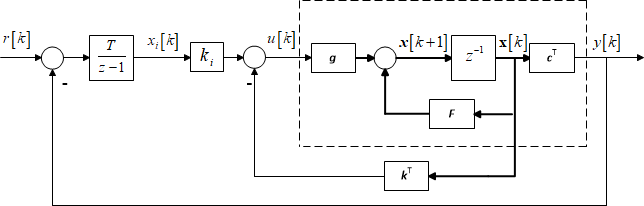

**Figure 4.2:** Integral action with a state feedback loop

The state equation of the closed loop system with state feedback supposing d=0 is the following:


$$\left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\left\lbrack k+1\right\rbrack \\
x_i \left\lbrack k+1\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
F-\mathit{\mathbf{g}}\;{\mathit{\mathbf{k}}}^T  & \mathit{\mathbf{g}}k_i \\
-{T\;\mathit{\mathbf{c}}}^T  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\left\lbrack k\right\rbrack \\
x_i \left\lbrack k\right\rbrack 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
T
\end{array}\right\rbrack r\left\lbrack k\right\rbrack$$



$$y\left\lbrack k\right\rbrack =\left\lbrack \begin{array}{cc}
{\mathit{\mathbf{c}}}^T  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\left\lbrack k\right\rbrack \\
x_i \left\lbrack k\right\rbrack 
\end{array}\right\rbrack +0\cdot \;r\left\lbrack k\right\rbrack$$


#### 4.2 State feedback of a third order discrete process extended with an integrator

This section illustrates the use of integral action on a the third order process given in example 3.1 with an integrator and a state feedback controller for the extended system.

disp('SECTION 4.1: DESIGN A STATE FEEDBACK CONTROLLER FOR A DISCRETE PROCESS EXTENDED WITH INTEGRATOR')

SECTION 4.1: DESIGN A STATE FEEDBACK CONTROLLER FOR A DISCRETE PROCESS EXTENDED WITH INTEGRATOR


clear
num=6.2;
den=poly([-1,-2,-3]);
[A,b,c,d]=tf2ss(num,den);  % The controllability canonical form of the state equation
Hc=ss(A,b,c,d);
T=0.2; %The sampling time
disp('The discrete state equation')

The discrete state equation


Hd=c2d(Hc,T,'zoh');
[F,g,cd,dd]=ssdata(Hd)

F =     0.1977   -1.2693   -0.6483
    0.1081    0.8461   -0.0807
    0.0135    0.1888    0.9940


g =     0.1081
    0.0135
    0.0010


cd =          0         0    6.2000


dd = 0


% Control design and inclusion of the integrator
disp('Parameter matrices of the extended system')

Parameter matrices of the extended system


Fe=[F zeros(3,1);T*cd 1];
ge=[g;0];
ce=[c 0];
de=d;
He=ss(Fe,ge,ce,de,T)

He =
 
  A = 
             x1        x2        x3        x4
   x1    0.1977    -1.269   -0.6483         0
   x2    0.1081    0.8461  -0.08071         0
   x3   0.01345    0.1888     0.994         0
   x4         0         0      1.24         1
 
  B = 
              u1
   x1     0.1081
   x2    0.01345
   x3  0.0009927
   x4          0
 
  C = 
        x1   x2   x3   x4
   y1    0    0  6.2    0
 
  D = 
       u1
   y1   0
 
Sample time: 0.2 seconds
Discrete-time state-space model.


disp('The prescribed poles of the discrete closed loop system')

The prescribed poles of the discrete closed loop system


pe=[-9 -6 -3+i*4 -3-i*4];
pd=exp(pe*T)

pd =    0.1653 + 0.0000i   0.3012 + 0.0000i   0.3824 + 0.3937i   0.3824 - 0.3937i


disp('The state feedback vector')

The state feedback vector


ke=acker(Fe,ge,pd)

ke =     6.7401   60.9170  260.8297   56.1552


kk=ke(1:3);
ki=ke(4);

The first three elements of the extended state feedback vector realise the state feedback from the original state variables, while the fourth element belongs to the artificially introduced integrator.

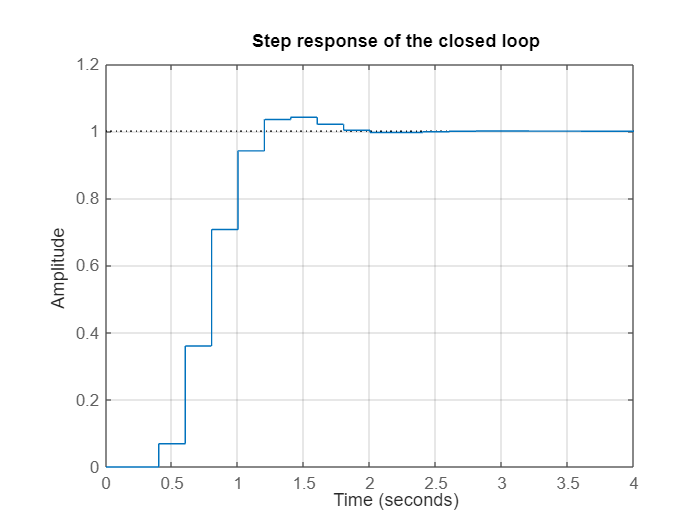

% Closed-loop simulation and the state matrices of the closed loop system
Fc=[F-g*kk g*ki;-T*c 1];
gc=[zeros(3,1);T];
cc=ce;
dc=0;
Hdc=ss(Fc,gc,cc,dc,T);
step(Hdc),grid
title('Step response of the closed loop')

## **5. State estimation**

In practical applications generally only the output signal can be measured and the state variables or some of the state variables are not available. In this case the state variables have to be estimated. The block scheme of the state estimator is shown in the figure 5.1 below. The estimator contains the model of the system. It is assumed that d=0. 

For slower explanations see: ***observer_design_control101, state_space_and_simulinkfile2_control101, state_space_and_simulinkfile3_control101***.

                            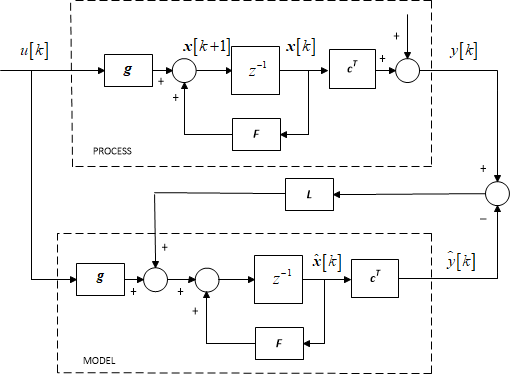

**Figure 5.1:** Open-loop diagram with an observer

If the system is known, the parameter matrices of the model are the same as the parameter matrices of the system. The deviation between the output signal of the system and that of the model is caused mainly by the difference of the initial conditions of the system and those supposed in the model. This error signal is fed back to the summing point at the derivatives of the estimated state variables and modifies their values. The estimated state variables should move quickly to approximate the motion of the real state variables. An important requirement is that the dynamics of the estimation circuit should be much faster than the dynamics of the process itself. The state estimation circuit forms a closed loop where the input signal is y (i.e.the output signal of the process). 

The free motion of the system states is to be estimated, i.e. the motion of the state variables starting from their initial values, supposing zero input signal. The disturbance signal is supposed to be zero.

The estimated state variables can be calculated as:


$$\hat{\mathit{\mathbf{x}}} \left\lbrack k+1\right\rbrack =F\hat{\mathit{\mathbf{x}}} \left\lbrack k\right\rbrack +\mathit{\mathbf{g}}\;u\left\lbrack k\right\rbrack +\mathit{\mathbf{L}}{\mathit{\mathbf{c}}}^T \left(\mathit{\mathbf{x}}\left\lbrack k\right\rbrack -\hat{x} \left\lbrack k\right\rbrack \right)=\left(\mathit{\mathbf{F}}-\mathit{\mathbf{L}}{\mathit{\mathbf{c}}}^T \right)\hat{\mathit{\mathbf{x}}} \left\lbrack k\right\rbrack +\textrm{Ly}\left\lbrack k\right\rbrack +\mathit{\mathbf{g}}\;u\left\lbrack k\right\rbrack$$


Introducing the error signal $\varepsilon \left\lbrack k\right\rbrack =\mathit{\mathbf{x}}\left\lbrack k\right\rbrack -\hat{\mathit{\mathbf{x}}} \left\lbrack k\right\rbrack$


$$\varepsilon \left\lbrack k+1\right\rbrack =\mathit{\mathbf{F}}\varepsilon \left\lbrack k\right\rbrack -\mathit{\mathbf{L}}{\mathit{\mathbf{c}}}^T \varepsilon \left\lbrack k\right\rbrack =\mathit{\mathbf{F}}\varepsilon \left\lbrack k\right\rbrack -\mathit{\mathbf{L}}\left(y\left\lbrack k\right\rbrack -\hat{y} \left\lbrack k\right\rbrack \right)$$


The poles of the estimation circuit can be prescribed. If the prescribed roots of the characteristic equation are denoted by *Pe*, the vector* L* can be calculated by the Ackermann formula by matlab command:

***L=acker(F',c',Pe)'***

#### State estimation of the state variables of a third order process - open-loop case

This section provides illustrative code on the design on an observer for a discrete system, for now used solely in open-loop.

disp('SECTION 5: ESTIMATE THE STATE VARIABLES OF A DISCRETE THIRD ORDER PROCESS')

SECTION 5: ESTIMATE THE STATE VARIABLES OF A DISCRETE THIRD ORDER PROCESS



num=6.2;
den=poly([-1,-2,-3]);
G=tf(num,den);
[A,b,c,d]=tf2ss(num,den); % The controllability canonical form of the continuous state equation
Hc=ss(A,b,c,d);
T=0.2;  % The sampling time
% The discrete state equation
Hd=c2d(Hc,T,'zoh');
[F,g,cd,dd]=ssdata(Hd);

% Observer design
disp('Prescribed poles of the continuous state estimation circuit')

Prescribed poles of the continuous state estimation circuit


Pc=[-7 -7 -7]

Pc =     -7    -7    -7


disp('Poles of the discrete state estimation circuit')

Poles of the discrete state estimation circuit


Pd=exp(Pc*T)

Pd =     0.2466    0.2466    0.2466


disp('Parameters of the estimation (elements of vector L)')

Parameters of the estimation (elements of vector L)


L=acker(F',cd',Pd)'

L =    -0.7460
    0.1996
    0.2094


Fest=F-L*cd;
% Parameters of the estimation model
sysest=ss(Fest,L,cd,dd,T);

% Simulation studies on the efficacy of the observer
disp('The true initial conditions')

The true initial conditions


x0=[1;1;1]

x0 =      1
     1
     1


t=0:T:6;
[y,t,x]=initial(Hd,x0,t);  % true state evolution
disp('Initial state variables in the estimation circuit')

Initial state variables in the estimation circuit


x0est=[0;0;0]

x0est =      0
     0
     0


[yest,t,xest]=lsim(sysest,y,t,x0est);
stairs(t,x),hold

Current plot held


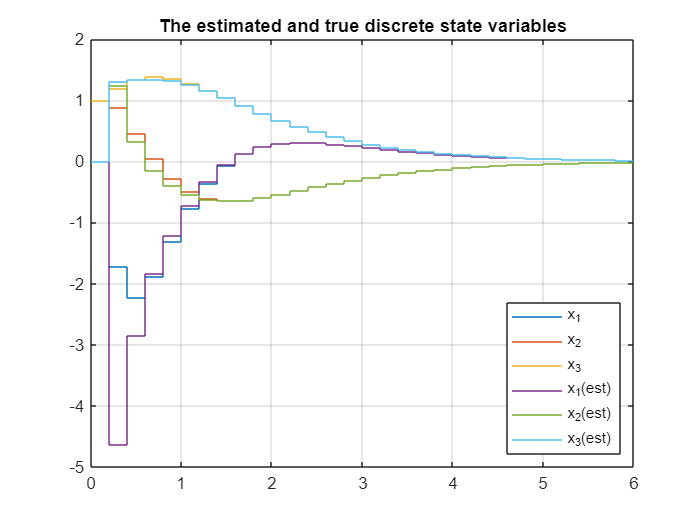

Current plot released


stairs(t,xest),grid
legend('x_1','x_2','x_3','x_1(est)','x_2(est)','x_3(est)','Location','southeast')
title('The estimated and true discrete state variables')
hold

stairs(t,y),hold

Current plot held


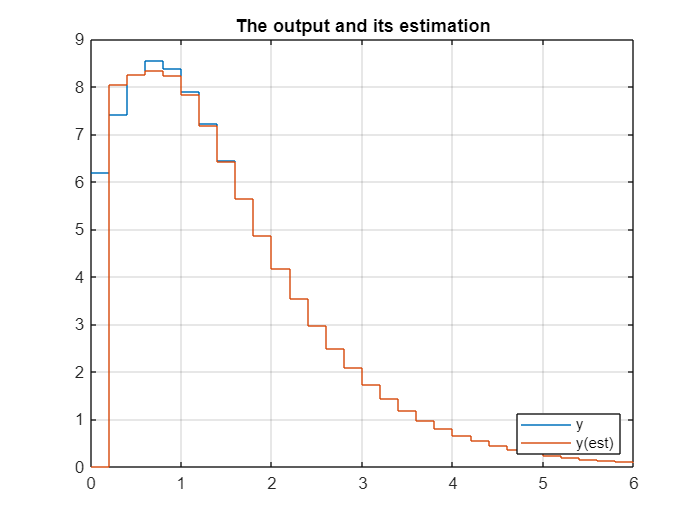

Current plot released


stairs(t,yest),grid
legend('y','y(est)','Location','southeast')
title('The output and its estimation')
hold

## **6. State feedback with state estimation**

If the state variables are not available, then state feedback control can be realised by feeding back the estimated state variables with the state feedback vector calculated for the original state variables (separation principle). The dynamics of the state feedback circuit would typically be faster than the process dynamics, and the dynamics of the state estimation circuit should be faster than the dynamics of the state feedback circuit.

The block diagram of the state feedback circuit using state estimation (observer) is given in the figure 6.1 below.

                            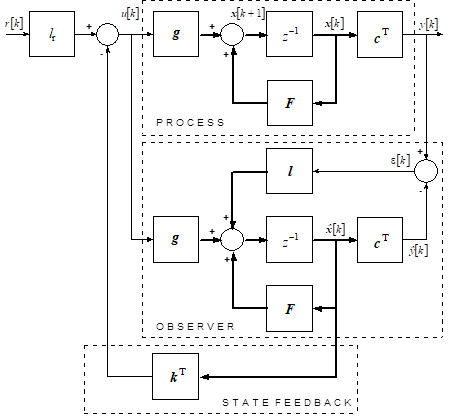

**Figure 6.1:** Closed-loop diagram with both integral action and an observer

The state equations of the system with state estimation and state feedback are:


$$\left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\left\lbrack k+1\right\rbrack \\
\hat{\mathit{\mathbf{x}}} \left\lbrack k+1\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\mathit{\mathbf{F}} & -\mathit{\mathbf{g}}\;{\mathit{\mathbf{k}}}^T \\
\mathit{\mathbf{L}}{\mathit{\mathbf{c}}}^T  & \mathit{\mathbf{F}}-\mathit{\mathbf{L}}{\mathit{\mathbf{c}}}^T -\mathit{\mathbf{g}}\;{\mathit{\mathbf{k}}}^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\left\lbrack k\right\rbrack \\
\hat{\mathit{\mathbf{x}}} \left\lbrack k\right\rbrack 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
k_r \;\mathit{\mathbf{g}}\\
k_r \;\mathit{\mathbf{g}}
\end{array}\right\rbrack r\left\lbrack k\right\rbrack$$



$$y\left\lbrack k\right\rbrack =\left\lbrack \begin{array}{cc}
{\mathit{\mathbf{c}}}^T  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\mathit{\mathbf{x}}\left\lbrack k\right\rbrack \\
\hat{\mathit{\mathbf{x}}} \left\lbrack k\right\rbrack 
\end{array}\right\rbrack +0\cdot r\left\lbrack k\right\rbrack$$


The code below steps through the entire design covering: i) discretisation of the model; ii) adding feedforward; iii) pole placement state feedback design; iv) observer design; v) forming the entire closed-loop system.  Also, it compares the behaviour of the closed-loop system when state feedback is taken from either the estimated or true states. Integral action is omitted from this section.

disp('SECTION 6: STATE FEEDBACK CONTROLLER FROM THE ESTIMATED STATES, DISCRETE CASE')

SECTION 6: STATE FEEDBACK CONTROLLER FROM THE ESTIMATED STATES, DISCRETE CASE



disp('The process')

The process


num=6.2;
den=poly([-1,-2,-3]);
G=tf(num,den)

G =
 
           6.2
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.
Model Properties


% The discrete state equation
T=0.2;
Hd=c2d(G,T,'zoh');
[F,g,cd,dd]=ssdata(Hd);
Hd1=ss(F,g,cd,dd);

% feedback design
Rc=[-6;-3+i*4;-3-i*4]; % The prescribed poles of the continuous closed loop system
disp('The prescribed poles of the discrete system')

The prescribed poles of the discrete system


Rd=exp(Rc*T)

Rd =    0.3012 + 0.0000i
   0.3824 + 0.3937i
   0.3824 - 0.3937i


disp('The discrete state feedback vector')

The discrete state feedback vector


k=acker(F,g,Rd)

k =     7.7756   -6.6760    3.3676


% The parameter matrices of the closed loop
Fc=F-g*k; gc=g; cc=cd;dc=dd;
Tk=ss(Fc,gc,cc,dc,T);
disp('The static gain')

The static gain


kr=1/dcgain(Tk)

kr = 13.4552

% The compensated state matrices
Fck=Fc;gck=kr*gc;cck=cc;dck=dc;
Tk1=ss(Fck,gck,cck,dck,T);

% Observer design
Pc=[-7 -7 -7]; % Prescribed poles of the continuous state estimation circuit
disp('Poles of the discrete state estimator')

Poles of the discrete state estimator


Pd=exp(Pc*T)

Pd =     0.2466    0.2466    0.2466


disp('Parameters of the estimation (elements of vector L)')

Parameters of the estimation (elements of vector L)


L=acker(F',cd',Pd)'

L =     6.6177
    5.8510
    2.1140



% Forming closed-loop state space model with feedback, feedforward and
% observer
Fext=[F -g*k;L*cd F-L*cd-g*k];
gext=[kr*g;kr*g];
cext=[cd zeros(1,3)];
dext=d;
Hext=ss(Fext,gext,cext,dext,T);

% Closed-loop simulations
disp('Initial conditions of estimator and process');

Initial conditions of estimator and process


x0=[0.2;0.2;0.2]

x0 =     0.2000
    0.2000
    0.2000


x0est=[0;0;0]

x0est =      0
     0
     0


x0f=[x0;x0est];
t=0:0.2:4;
% full state feedback
[y1,t,x]=initial(Tk1,x0,t); % initial conditions only
y2=step(Tk1,t);             % response to change in the target
y=y1+y2;                    % total response
% With an observer
[y3,t,x3]=initial(Hext,x0f,t);
y4=step(Hext,t);
y5=y3+y4;
% plots
stairs(t,y),hold

Current plot held


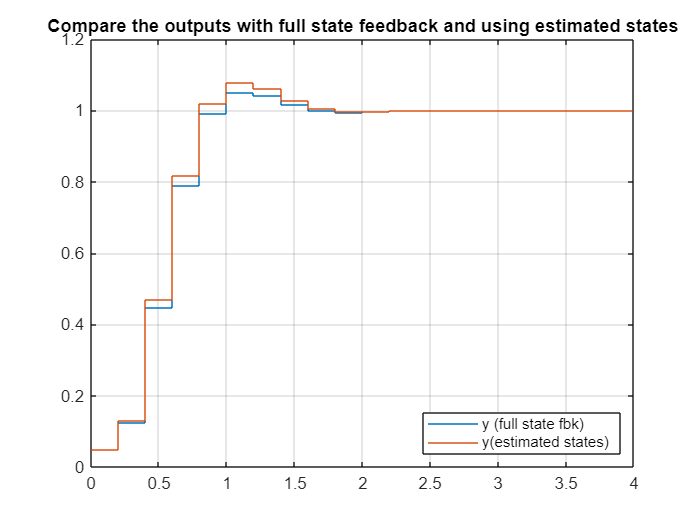

Current plot released


stairs(t,y5),grid
legend('y (full state fbk)','y(estimated states)','Location','Southeast')
title('Compare the outputs with full state feedback and using estimated states')
hold

It is seen that the estimation of the state variables is acceptable and the control is good for both cases, when the state feedback is taken from the original states or from the estimated state variables.